%{
Project Name: Solar Tracker
Author: Kanak Sharma
Email: kanak.sharma1031@gmail.com
Date: 2024-06-25
License: This project is licensed under the MIT License - see the LICENSE file for details.
%}
% Define the date, time, and location parameters
year = 2024;   % Year of the calculation
month = 5;     % Month (May)
day = 25;      % Day (25th of the month)
hours = 16;    % Time of day in hours (16 hours = 4:00 PM)
minutes = 5;   % Minutes
seconds = 0;   % Seconds
tz = 5.5;      % Time zone (IST = UTC + 5.5 hours)
lat = 28;      % Latitude of the location (28 degrees)
long = 78;     % Longitude of the location (78 degrees)

% Create a datetime object for reference
dd = datetime(year, month, day, hours, minutes, seconds);
% Array
tilt_angles = zeros(1, 24);
solar_ae = zeros(1,24); solar_az = zeros(1,24);
Table = zeros(24, 3);
azimuth_angles = zeros(1, 24);

%Reference:
% The NOAA Solar Calculator provides solar position calculations
% based on latitude, longitude, date, and time. These values are 
% essential for determining the optimal positioning of solar panels 
% to maximize energy absorption.
for i = 1:24
    % Calculate e2 as the fraction of the day passed
    e = (i-1)/24;
    % Calculate the Julian date
    a = floor((14 - month) / 12);
    y = year + 4800 - a;
    m = month + 12 * a - 3;
    jd = day + floor((153 * m + 2) / 5) + 365 * y + floor(y / 4) - floor(y / 100) + floor(y / 400) - 32045;
    jd = jd + (hours - 12) / 24 + minutes / 1440 + seconds / 86400; 
    julian = jd + e - (tz / 24);
    % Calculate Julian century
    julian_cent = (julian - 2451545) / 36525;
    i2 = mod(280.46646 + julian_cent * (36000.76983 + julian_cent * 0.0003032), 360);
    j2 = 357.52911+julian_cent*(35999.05029-0.0001537*julian_cent);
    k2 = 0.016708634 - julian_cent*(0.000042037+0.0000001267*julian_cent);
    % Calculate the sun's equation of the center
    l2 = sin(deg2rad(j2))*(1.914602-julian_cent*(0.004817+0.000014*julian_cent))+sin(deg2rad(2*j2))*(0.019993-0.000101*julian_cent)+sin(deg2rad(3*j2))*0.000289;
    m2=i2+l2;
    n2 = j2 + l2;
    o2 = (1.000001018*(1-k2*k2))/(1+k2*cos(deg2rad(n2)));
    p2 = m2 - 0.00569 - 0.00478 * sin(deg2rad(125.04-1934.136*julian_cent));
    q2 = 23 + (26+((21.448-julian_cent*(46.815+julian_cent*(0.00059-julian_cent*0.001813))))/60)/60;
    r2 = q2+ 0.00256*cos(deg2rad(125.04-1934.136*julian_cent));
    % Calculate the sun's right ascension
    s2 = rad2deg(atan2(cos(deg2rad(p2)),cos(deg2rad(r2))*sin(deg2rad(p2))));
    t2 = rad2deg(asin(sin(deg2rad(r2))*sin(deg2rad(p2))));
    % Calculate the equation of time
    u = tan(deg2rad(r2/2))*tan(deg2rad(r2/2));
    v = 4*rad2deg(u*sin(2*deg2rad(i2))-2*k2*sin(deg2rad(j2))+4*k2*u*sin(deg2rad(j2))*cos(2*deg2rad(i2))-0.5*u*u*sin(4*deg2rad(i2))-1.25*k2*k2*sin(2*deg2rad(j2)));
    % Calculate the hour angle of sunrise
    w = rad2deg(acos(cos(deg2rad(90.833))/(cos(deg2rad(lat))*cos(deg2rad(t2)))-tan(deg2rad(lat))*tan(deg2rad(t2))));
    x = (720-4*lat-v+tz*60)/1440;
    % Calculate sunrise and sunset times
    y2 = x-w*4/1440;
    z2 = x+w*4/1440;
    % Calculate the duration of sunlight in minutes
    aa = 8*w;
    ab = mod(e*1440+v+4*long-60*tz,1440);
    ab2 = ab ; 
    %Calculations for Elevation and Azimuth angles
    if ab2 / 4 < 0
        ac = ab2 / 4 + 180;
    else
        ac = ab2 / 4 - 180;
    end
    ad = rad2deg(acos(sin(deg2rad(lat))*sin(deg2rad(t2))+cos(deg2rad(lat))*cos(deg2rad(t2))*cos(deg2rad(ac))));
    %elevation angle 
    ae = 90 - ad;
    tilt_angles(i)=ae;
    if ac > 0
        ah = mod(rad2deg(acos(((sin(deg2rad(lat))*cos(deg2rad(ad)))-sin(deg2rad(t2)))/(cos(deg2rad(lat))*sin(deg2rad(ad)))))+180, 360);
    else
        ah = mod(540 - rad2deg(acos(((sin(deg2rad(lat))*cos(deg2rad(ad)))-sin(deg2rad(t2)))/(cos(deg2rad(lat))*sin(deg2rad(ad))))), 360);
    end

    %azimuth angle for tracker
    azimuth_angles(i)=ah;

    %Integration in the format of a Table for Display
    Table(i, 1) = i-1; 
    Table(i, 2) = ae;
    Table(i, 3) = ah; 
    solar_ae(i)=ae;
    solar_az(i)=ah;
    %Changes done for Night time
        if tilt_angles(i) > 0
            tilt_angles(i) = 90-tilt_angles(i); 
        end        

        if tilt_angles(i) <= 0
            azimuth_angles(i) = 0; 
            tilt_angles(i) = 90;
        end

end
ColumnNames = {'Hour', 'Elevation angles', 'Azimuth angles'};
T = array2table(Table, 'VariableNames', ColumnNames)

T = 24×3 table
    Hour    Elevation angles    Azimuth angles
    ____    ________________    ______________

      0         -40.788             355.38    
      1         -39.725             13.688    
      2         -34.743             30.141    
      3         -26.766             43.544    
      4         -16.775             54.107    
      5         -5.4927             62.548    
      6          6.6156             69.562    
      7          19.256             75.717    
      8          32.236             81.517    
      9          45.415             87.563    
     10          58.649             95.008    
     11          71.644             107.72    
     12          82.358             152.59    
     13          77.723             238.69    
     14          65.247             259.87    
     15          52.074             269.06    


% Assuming the stepper motor moves in fixed steps (e.g., 1.8 degrees per step)
stepAngle=1.8;
    
% Calculate the number of steps required for azimuth
azimuthSteps = round(azimuth_angles / stepAngle);
    
% Calculate the number of steps required for elevation
elevationSteps = round(tilt_angles / stepAngle);


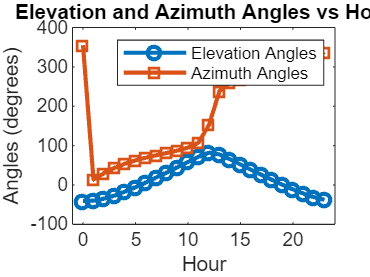

% Plotting Elevation Angles and Azimuth Angles
figure; % Create a new figure window

% Plot Elevation Angles
plot(T.Hour,T.("Elevation angles"), '-o', 'LineWidth', 2, 'DisplayName', 'Elevation Angles'); 
hold on; % Keep the current plot

% Plot Azimuth Angles
plot(T.Hour, T.("Azimuth angles"), '-s', 'LineWidth', 2, 'DisplayName', 'Azimuth Angles'); 

% Adding Title and Labels
title('Elevation and Azimuth Angles vs Hour'); % Title of the plot
xlabel('Hour'); % X-axis label
ylabel('Angles (degrees)'); % Y-axis label

% Adding a Legend
xlim([-1 24]); % Set x-axis limits
legend('show'); % Show legend with display names

% Create timeseries for irradiance 
values1 = elevationSteps(1,:);
values1 = values1(1,2:24);
time = 1:23;
signal = timeseries(values1, time);
dataset = Simulink.SimulationData.Dataset;
dataset = dataset.addElement(signal, 'elevation_signal_data');
save('elevation_signal_data.mat', 'dataset');

values2 = azimuthSteps(1,:);
values2 = values2(1,2:24);
signal = timeseries(values2, time);
dataset = Simulink.SimulationData.Dataset;
dataset = dataset.addElement(signal, 'azimuth_signal_data');
save('azimuth_signal_data.mat', 'dataset');
